## AAE 440 PS11 

clear all; close all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Spring\AAE440\MATLAB\outputs\HW11';
set(groot, 'defaulttextinterpreter','latex');  
set(groot, 'defaultAxesTickLabelInterpreter','latex');  
set(groot, 'defaultLegendInterpreter','latex');

###  1b)

% Defining the object
Ia = 425;  % [kg-m2]
Ib = 500;  % [kg-m2]
Ic = 125;  % [kg-m2]

% Orientation (i)
I1_i = Ia; 
I2_i = Ic;
I3_i = Ib;
I_i = [I1_i I2_i I3_i];
% Orientation (ii)
I1_ii = Ia; 
I2_ii = Ib;
I3_ii = Ic;
I_ii = [I1_ii I2_ii I3_ii];
% Orientation (iii)
I1_iii = Ib; 
I2_iii = Ia;
I3_iii = Ic;
I_iii = [I1_iii I2_iii I3_iii];
% Orientation (iv)
I1_iv = Ic; 
I2_iv = Ia;
I3_iv = Ib;
I_iv = [I1_iv I2_iv I3_iv];

% All orientations 
Is = [I_i; I_ii; I_iii; I_iv];

% Compute K-values 
Ks = zeros(size(Is));
for i = 1:size(Is,1)
    Ks(i,:) = calc_Kvalues(Is(i,:));
end
Ks_T = array2table(Ks,"VariableNames",{'K1','K2','K3'});
writetable(Ks_T,fullfile(fdir,'Kvalues_table.xlsx'),"WriteMode","overwritesheet");

### 1c)

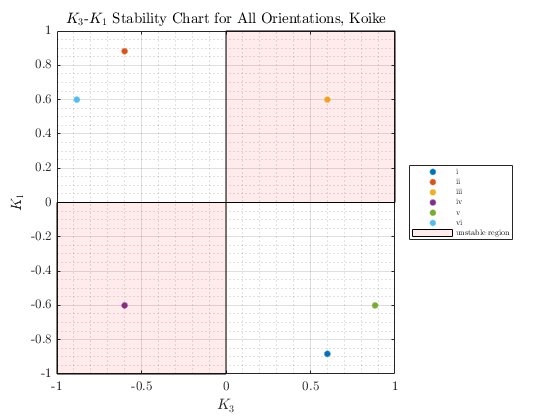

% All possible permutations/orientations
P_33 = perms(["a","b","c"]);

% Missing oreientations 
% Orientation (v)
I1_v = Ib; 
I2_v = Ic;
I3_v = Ia;
I_v= [I1_v I2_v I3_v];
% Orientation (vi)
I1_vi = Ic; 
I2_vi = Ib;
I3_vi = Ia;
I_vi = [I1_vi I2_vi I3_vi];

% Add the missing orientations 
Is_new = [Is; I_v; I_vi];
for i = 1:size(Is_new,1)
    Ks_new(i,:) = calc_Kvalues(Is_new(i,:));
end
% Overwrite previous orientation table 
Ks_T_new = array2table(Ks_new,"VariableNames",{'K1','K2','K3'});
writetable(Ks_T_new,fullfile(fdir,'Kvalues_table.xlsx'),"WriteMode","overwritesheet");

% K3-K1 stability chart 
fig = figure("Renderer","painters");
    for i = 1:size(Ks_new,1)
        plot(Ks_new(i,3),Ks_new(i,1),'.',"MarkerSize",15)
        if i == 1 hold on, end
    end
    v = [0 0; 1 0; 1 1; 0 1; 0 0; -1 0; -1 -1; 0 -1]; f = [1 2 3 4; 5 6 7 8];
    patch("Faces",f,"Vertices",v,"FaceColor",'red','FaceAlpha',0.08);
    A = linspace(-1,1); B = zeros(size(A));
    plot(A,B,'--k',"LineWidth",0.8); plot(B,A,'--k',"LineWidth",0.8); hold off; 
    title('$K_3$-$K_1$ Stability Chart for All Orientations, Koike')
    xlabel('$K_3$'); ylabel('$K_1$');
    lgd = legend('i','ii','iii','iv','v','vi','unstable region',"Location","eastoutside");
    lgd.FontSize = 6;
    xlim([-1 1]); ylim([-1 1]); grid on; grid minor; box on;
saveas(fig,fullfile(fdir,"K3-K1_stability_chart.png"));

### 2d)

% Computing the eigenavlues for each orientation
lambda = zeros(7,length(Ks_new));
for i = 1:length(Ks_new)
    lambda(:,i) = eigenvalues_unsymmBody(Ks_new(i,1), Ks_new(i,2), Ks_new(i,3));
end

lambda_arr = [lambda(:,1) lambda(:,2) lambda(:,3) ...
             lambda(:,4) lambda(:,5) lambda(:,6)];
% Write array to excel sheet for convenience 
b = arrayfun(@num2str,lambda_arr,'un',0);
xlswrite(fullfile(fdir,'eigenval_P2d.xlsx'),b);

### 2e)

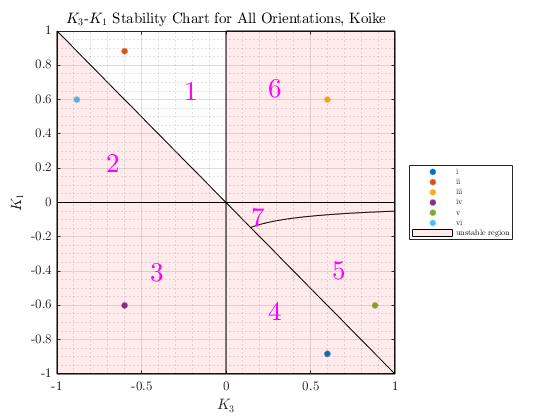

% K3-K1 stability chart with stability constraints 
fig = figure("Renderer","painters");
    for i = 1:size(Ks_new,1)
        plot(Ks_new(i,3),Ks_new(i,1),'.',"MarkerSize",15)
        if i == 1 hold on, end
    end
    v = [0 0;1 0;1 1;0 1;0 0;-1 0;-1 -1;0 -1]; v2 = [-1 0;-1 1;0 0;0 0;0 -1;1 -1]; 
    f = [1 2 3 4; 5 6 7 8]; f2 = [1 2 3; 4 5 6];
    patch("Faces",f,"Vertices",v,"FaceColor",'red','FaceAlpha',0.08);
    patch("Faces",f2,"Vertices",v2,"FaceColor",'red','FaceAlpha',0.08);
    
    % Region 5
    x = 0.1459:0.001:1;
    roots = zeros(1,length(x));
    for i = 1:length(x)
        func = @(y) (1-x(i).*y+3.*y).^2 + 16.*x(i).*y;
        roots(i) = fzero(func,0);
    end
    plot(x,roots, 'k-')
    
    v3 = [0 0;1 0;1 -1]; f3 = [1 2 3];
    patch("Faces",f3,"Vertices",v3,"FaceColor",'red','FaceAlpha',0.08);
    
    A = linspace(-1,1); B = zeros(size(A));
    plot(A,B,'--k',"LineWidth",0.8); plot(B,A,'--k',"LineWidth",0.8); hold off; 
    title('$K_3$-$K_1$ Stability Chart for All Orientations, Koike')
    xlabel('$K_3$'); ylabel('$K_1$');
    lgd = legend('i','ii','iii','iv','v','vi','unstable region',"Location","eastoutside");
    lgd.FontSize = 6;
    xlim([-1 1]); ylim([-1 1]); grid on; grid minor; box on;
    
    % Add texts
    text(-0.25,0.63,'1',"FontSize",20,"FontWeight","bold","Color",'m');
    text(-0.71,0.21,'2',"FontSize",20,"FontWeight","bold","Color",'m');
    text(-0.45,-0.42,'3',"FontSize",20,"FontWeight","bold","Color",'m');
    text(0.25,-0.65,'4',"FontSize",20,"FontWeight","bold","Color",'m');
    text(0.63,-0.41,'5',"FontSize",20,"FontWeight","bold","Color",'m');
    text(0.25,0.65,'6',"FontSize",20,"FontWeight","bold","Color",'m');
    text(0.15,-0.10,'7',"FontSize",20,"FontWeight","bold","Color",'m');
    
saveas(fig,fullfile(fdir,"K3-K1_stability_chart2.png"));

close all;

### 3c)

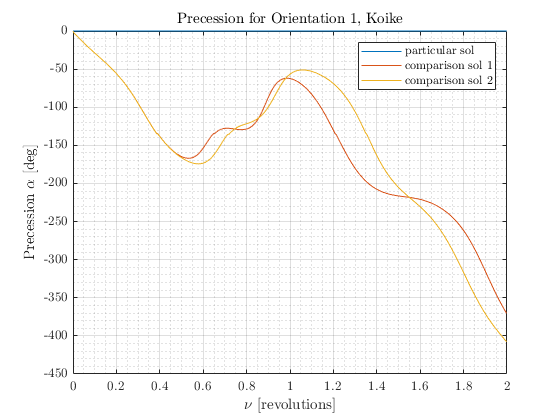

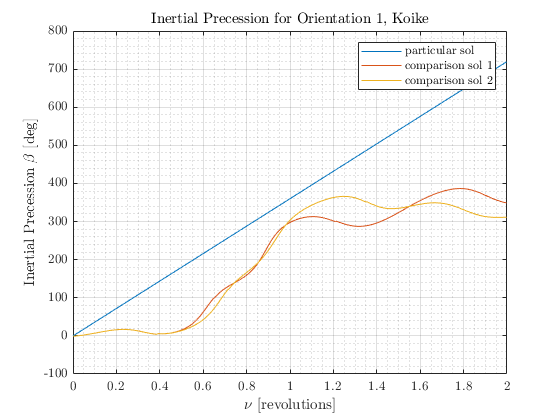

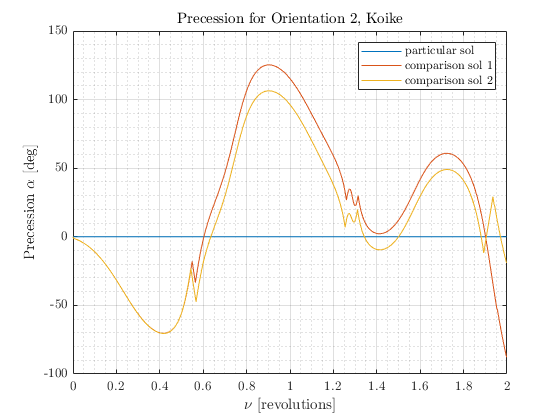

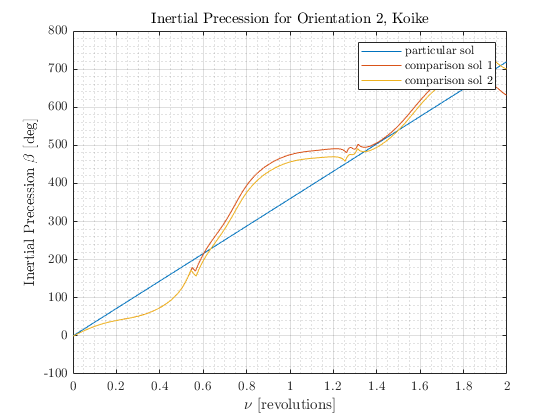

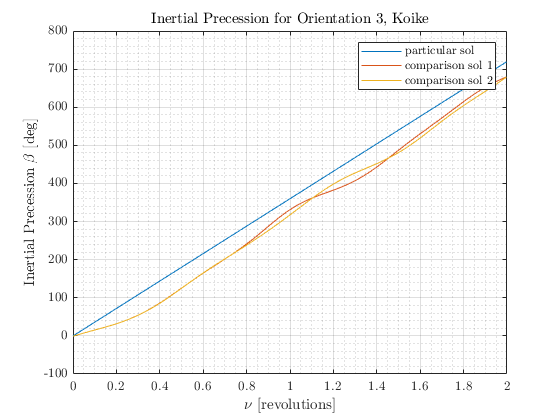

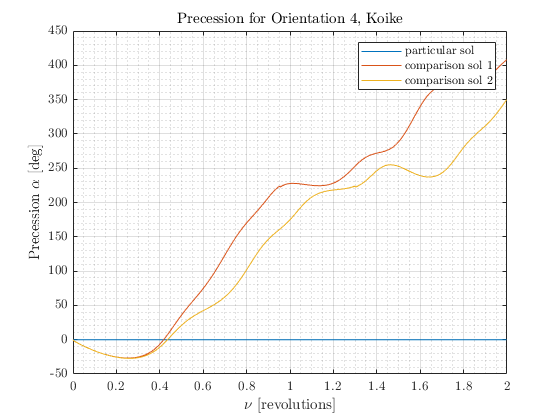

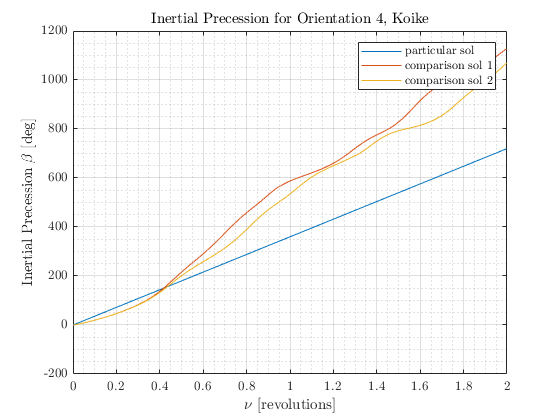

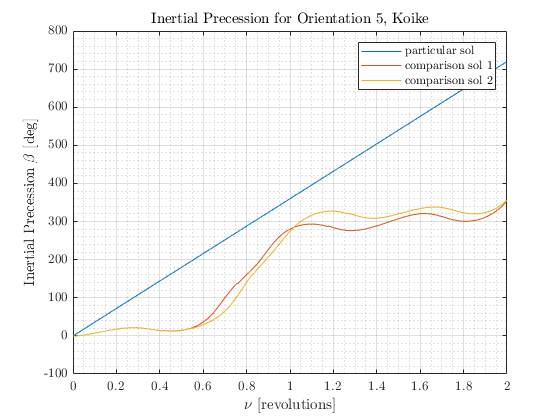

K1 = Ks_new(:,1).';
K2 = Ks_new(:,2).';
K3 = Ks_new(:,3).';
N = length(K1);

for k = 1:2
    % Revolutions
    v = [2 10];
    rev = 0:0.003:v(k);
    
    for j = 1:N % for different orientations
    
        for i = 1:3 % for different intial w
            w1 = [0 0.12 0.06]; w2 = [1 1 1]; w3 = [0 0.12 0.06];
            w0 = [w1(i) w2(i) w3(i)];   % initial angular velocities
            e0 = [0 0 0 1];             % initial euler parameters
            y  = [w0 e0 0];             % Initial Conditions

            % Nutation and Precession History
            [rev, Nut, Prec] = Nut_Prec_UnsymmBody(rev,y,K1(j),K2(j),K3(j));
            
            % Plotting Precession Angle
            figure(j)
                hold on;
                if i == 1
                    plot(rev, Prec,'-','DisplayName','particular sol')
                else
                    plot(rev, Prec,'-','DisplayName',['comparison sol ',num2str(i-1)])
                end

            % Plotting Inertial Precession Angle
            sigma = 360*rev;
            beta = Prec+sigma;
            figure(j+N)
                hold on;
                if i == 1
                    plot(rev, beta,'-','DisplayName','particular sol')
                else
                    plot(rev, beta,'-','DisplayName',['comparison sol ',num2str(i-1)])
                end
        end
            fig1 = figure(j);
                xlabel('$\nu$ [revolutions]'); 
                ylabel('Precession $\alpha$ [deg]')
                grid on; grid minor; box on; legend;
                str = sprintf('Precession for Orientation %d, Koike',j);
                title(str)
                str = sprintf('3.(c)Alpha_ori%d_rev%d.png',j,v(k));
            saveas(fig1, fullfile(fdir, str));

            fig2 = figure(j+N);
                xlabel('$\nu$ [revolutions]'); 
                ylabel('Inertial Precession $\beta$ [deg]')
                grid on; grid minor; box on; legend;
                str = sprintf('Inertial Precession for Orientation %d, Koike',j);
                title(str)
                str = sprintf('3.(c)Beta_ori%d_rev%d.png',j,v(k));
            saveas(fig2, fullfile(fdir, str));
    end
    close all;
end

## 3e)

% Modified Moment of Inertia [kg m2]
I_a = 450;  I_b = 385;  I_c = 410;

% Shape Factors for the Modified Vehicle in Region 7
[K1_reg7, K2_reg7, K3_reg7] = K_from_orientation(I_a, I_b, I_c);

% K3-K1 Stability Chart
fig = figure(1);
    hold on
    plot(K3_reg7,K1_reg7,'r.',"MarkerSize",30)
    
    % Region 3 & 6 
    v = [0 0;1 0;1 1;0 1;0 0;-1 0;-1 -1;0 -1]; f = [1 2 3 4; 5 6 7 8];
    patch("Faces",f,"Vertices",v,"FaceColor",'red','FaceAlpha',0.08);
    
    % Region 2 & 4
    v2 = [-1 0;-1 1;0 0;0 0;0 -1;1 -1]; f2 = [1 2 3; 4 5 6];
    patch("Faces",f2,"Vertices",v2,"FaceColor",'red','FaceAlpha',0.08);
    
    % Separating Region 5 & 7
    x = 0.1459:0.001:1;
    roots = zeros(1,length(x));
    for i = 1:length(x)
        func = @(y) (1-x(i).*y+3.*y).^2 + 16.*x(i).*y;
        y0 = 0;
        roots(i) = fzero(func,y0);
    end
    plot(x,roots, 'k-')
    
    % Region 5 & 7
    v3 = [0 0;1 0;1 -1]; f3 = [1 2 3];
    patch("Faces",f3,"Vertices",v3,"FaceColor",'red','FaceAlpha',0.08);
    
    % Figure Properties
    title('$K_3$-$K_1$ Stability Chart with All Orientations, Koike')
    xlabel('$K_3$'); ylabel('$K_1$');
    lgd = legend('Modified Vehicle','Unstable Region',"Location","eastoutside");
    lgd.FontSize = 6;
    grid on; grid minor; axis equal; axis([-1 1 -1 1]);
    
    % Region Numbers
    text(-0.2,0.6,'1',"FontSize",20,"Color",'k');
    text(-0.6,0.2,'2',"FontSize",20,"Color",'k');
    text(-0.4,-0.4,'3',"FontSize",20,"Color",'k');
    text(0.2,-0.6,'4',"FontSize",20,"Color",'k');
    text(0.6,-0.2,'5',"FontSize",20,"Color",'k');
    text(0.4,0.4,'6',"FontSize",20,"Color",'k');
    text(0.3,-0.05,'7',"FontSize",15,"Color",'k');
saveas(fig,fullfile(fdir,"3.(e)K3-K1_stability_chart_region7.png"));

close all;

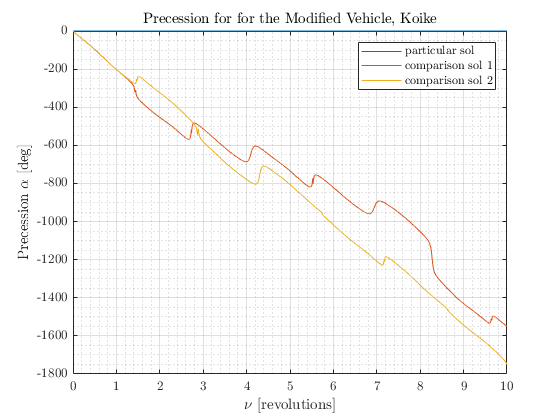

% Plotting Precessions for Modified Vehicle
rev = 0:0.001:10;
for i = 1:3 % for different intial w
    w1 = [0 0.12 0.06]; w2 = [1 1 1]; w3 = [0 0.12 0.06];
    w0 = [w1(i) w2(i) w3(i)];   % initial angular velocities
    e0 = [0 0 0 1];             % initial euler parameters
    y  = [w0 e0 0];             % Initial Conditions
    
    % Nutation and Precession History
    [rev, Nut, Prec] = Nut_Prec_UnsymmBody(rev,y,K1_reg7,K2_reg7,K3_reg7);
    
    % Plotting Precession Angle
    figure(1)
        hold on;
        if i == 1
            plot(rev, Prec,'-','DisplayName','particular sol')
        else
            plot(rev, Prec,'-','DisplayName',['comparison sol ',num2str(i-1)])
        end

    % Plotting Inertial Precession Angle
    sigma = 360*rev;
    beta = Prec+sigma;
    figure(2)
        hold on;
        if i == 1
            plot(rev, beta,'-','DisplayName','particular sol')
        else
            plot(rev, beta,'-','DisplayName',['comparison sol ',num2str(i-1)])
        end
end
    fig1 = figure(1);
        xlabel('$\nu$ [revolutions]'); 
        ylabel('Precession $\alpha$ [deg]')
        grid on; grid minor; box on; legend;
        str = sprintf('Precession for for the Modified Vehicle, Koike');
        title(str)
        str = sprintf('3.(e)Alpha_reg7.png');
    saveas(fig1, fullfile(fdir, str));

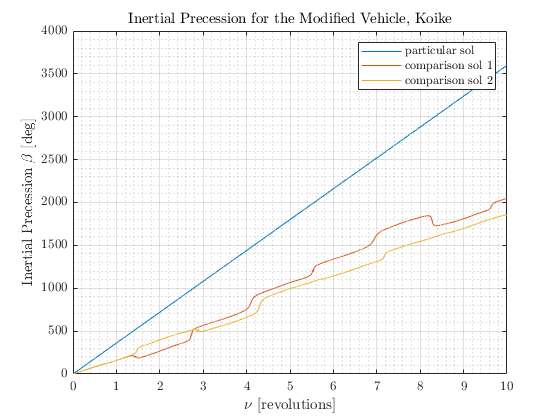

    
    fig2 = figure(2);
        xlabel('$\nu$ [revolutions]'); 
        ylabel('Inertial Precession $\beta$ [deg]')
        grid on; grid minor; box on; legend;
        str = sprintf('Inertial Precession for the Modified Vehicle, Koike');
        title(str)
        str = sprintf('3.(e)Beta_reg7.png');
    saveas(fig2, fullfile(fdir, str));

### Functions

function Ks = calc_Kvalues(I)
    I1 = I(1); I2 = I(2); I3 = I(3);
    K1 = (I2 - I3)/I1;
    K2 = (I3 - I1)/I2;
    K3 = (I1 - I2)/I3;
    Ks = [K1 K2 K3];
end